# Adjust and Regression commands

Clear workspace

clear all; clc; close all;

## Linear regression

y = [1.1 2.0 2.9 3.9 5.1 6.0 7.1 7.9 9.1 10.2]';
x = [0 1 2 3 4 5 6 7 8 9]';

### Polyfit --> linear regression

[p,S] = polyfit(x,y,1)

p =     1.0127    0.9727


S = struct with fields:
        R: [2×2 double]
       df: 8
    normr: 0.2960


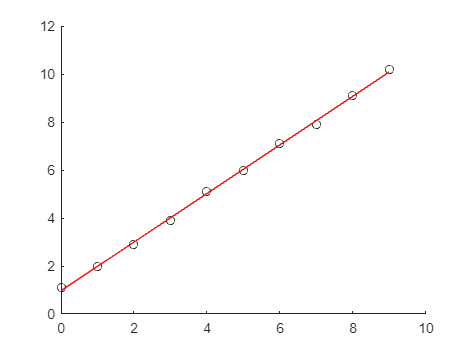


yfit = p(1)*x + p(2);
figure(1)
clf
hold on
plot(x,y,'ko')
plot(x,yfit,'r')
hold off

### Fit --> lineal regression

[f, gof, output] = fit(x,y,'poly1')

f =      Linear model Poly1:
     f(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       1.013  (0.9862, 1.039)
       p2 =      0.9727  (0.8309, 1.115)

gof = struct with fields:
           sse: 0.0876
       rsquare: 0.9990
           dfe: 8
    adjrsquare: 0.9988
          rmse: 0.1047


output = struct with fields:
        numobs: 10
      numparam: 2
     residuals: [10×1 double]
      Jacobian: [10×2 double]
      exitflag: 1
     algorithm: 'QR factorization and solve'
    iterations: 1


yfit = f.p1*x + f.p2;
figure(2)
clf
hold on
plot(x,y,'ko')
plot(x,yfit,'r')
hold off

### Regress --> lineal regression

X = [ones(size(x,1)) x];
[b, bint, r, rint, stats] = regress(y,X);

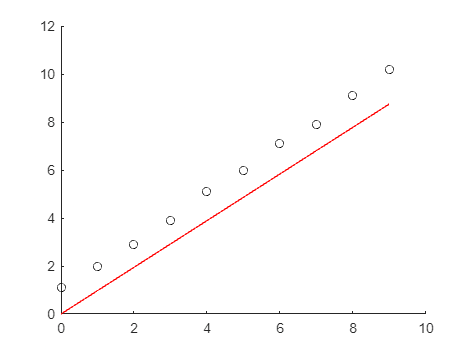


yfit = b(2)*x + b(1);
figure(3)
clf
hold on
plot(x,y,'ko')
plot(x,yfit,'r')
hold off

## Polynomical regression

x = [0.1 0.9 2.0 3.1 4.0 4.9 6.1 7.1 7.9 9.0 10.1]';
y = [-0.94 -0.17 1.37 2.27 3.40 3.83 4.18 3.83 3.09 1.42 -1.24]';

### Polyfit --> polynomical regression

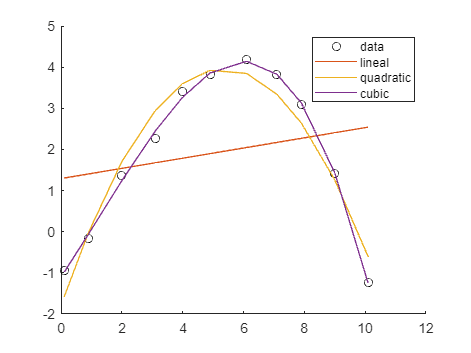

% Grade 1 polynomial
p1 = polyfit(x,y,1);
yfit1 = p1(1)*x + p1(2);

% Grade 2 polynomial
p2 = polyfit(x,y,2);
yfit2 = p2(1)*x.^2 + p2(2)*x + p2(3);

% Grade 3 polynomial
p3 = polyfit(x,y,3);
yfit3 = p3(1)*x.^3 + p3(2)*x.^2 + p3(3)*x + p3(4);

figure(4)
clf
hold on
plot(x,y,'ko')
plot(x,yfit1)
plot(x,yfit2)
plot(x,yfit3)
legend('data','lineal','quadratic','cubic')
hold off

### Fit --> polynomical regression

% Grade 1
[f1, gof, output] = fit(x,y,'poly1');
yfit1 = f1.p1*x + f1.p2;

% Grade 2
[f2, gof, output] = fit(x,y,'poly2');
yfit2 = f2.p1*x.^2 + f2.p2*x + f2.p3;

% Grade 1
[f3, gof, output] = fit(x,y,'poly3');
yfit3 = f3.p1*x.^3 + f3.p2*x.^2 + f3.p3*x + f3.p4;

figure(5)
clf
hold on
plot(x,y,'ko')
plot(x,yfit1)
plot(x,yfit2)
plot(x,yfit3)
legend('data','lineal','quadratic','cubic')
hold off

### Regress --> polynomical regression

X = [ones(size(x,1),1) x];
[b, bint, r, rint, stats] = regress(y,X);
yfit1 = b(2)*x + b(1);

X = [ones(size(x,1),1) x x.^2];
[b, bint, r, rint, stats] = regress(y,X);
yfit2 = b(3)*x.^2 + b(2)*x + b(1);

X = [ones(size(x,1),1) x x.^2 x.^3];
[b, bint, r, rint, stats] = regress(y,X);
yfit3 = b(4)*x.^3 + b(3)*x.^2 + b(2)*x + b(1);

figure(6)
clf
hold on
plot(x,y,'ko')
plot(x,yfit1)
plot(x,yfit2)
plot(x,yfit3)
legend('data','lineal','quadratic','cubic')
hold off

## Multivariant regression

x1 = [ 8.19  9.88  5.51  4.87  5.85  1.61  2.08  1.75  9.64  0.09]';
x2 = [ 1.47 -3.94  2.49  2.66  3.43 -3.60 -0.28 -4.34 -4.85  2.10]';
x3 = [ 0.32  0.33 -0.37 -0.56 -0.39  0.42  1.50 -1.00 -0.78 -0.27]';
x = [x1 x2 x3];
y = [11.66 18.86  1.35 -1.60  0.62 11.38 19.44 -1.66  8.75 -2.94]';

### regress --> multivariant regression

X=[ones(size(x,1),1) x1 x2 x3];
[b, bint, r, rint, stats] = regress(y,X);
b

b =     2.0282
    0.9821
   -1.0175
    9.9375


bint

bint =     1.7603    2.2961
    0.9364    1.0278
   -1.0654   -0.9697
    9.7216   10.1535


stats

stats = 1.0e+03 *

    0.0010    5.8743    0.0000    0.0000


### fitlm --> multivariant regression

X = [x1 x2 x3];
lm = fitlm(X,y)

lm = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     2.0282      0.10948     18.525    1.5958e-06
    x1             0.98207     0.018676     52.586    3.1741e-09
    x2             -1.0175      0.01955    -52.048    3.3755e-09
    x3              9.9375     0.088267     112.58    3.3105e-11


Number of observations: 10, Error degrees of freedom: 6
Root Mean Squared Error: 0.193
R-squared: 1,  Adjusted R-Squared: 0.999
F-statistic vs. constant model: 5.87e+03, p-value = 8.62e-11